# Getting Started with the Ground-Vehicle Project

**Waypoint Optimisation, Guidance, Navigation and Control, and State Estimation**

**Group 50**

School of Electrical Engineering and Robotics | Queensland University of Technology

[](mailto:chabod.masere@connect.qut.edu.au)

This MATLAB tutorial explains how to initialise, run and evaluate the integrated ground-vehicle project. It connects the waypoint planner, guidance and control, and the state estimator, then provides small numerical examples before the full Simulink workflow.

**How to use this file.** Open it in the MATLAB Live Editor using R2025a or later. Run the sections in order on the first pass. The calculations run with base MATLAB; the full vehicle simulation requires the complete project and its Simulink dependencies. Set Current Folder to your project root before enabling simulation. The two architecture images are embedded in this file.

MATLAB supports this formatted `.m` Live Code format from R2025a. You can use **Save As > MATLAB Live Code File (*.mlx)** in the Live Editor if your project requires an `.mlx` copy. See [MathWorks: Live Code file format](https://www.mathworks.com/help/matlab/matlab_prog/plain-text-file-format-for-live-scripts.html).

## 1. Project overview

GNC means guidance, navigation and control. State estimation provides the navigation information used in this project. The waypoint order defines where the robot must go; guidance uses its estimated location to choose a direction; control commands the vehicle; and the next measurements update the estimator.

Position error can change when guidance declares a waypoint captured. Heading error can change the turn command. This is why estimator performance must be assessed alongside route following and mission completion.

## 2. Full system architecture

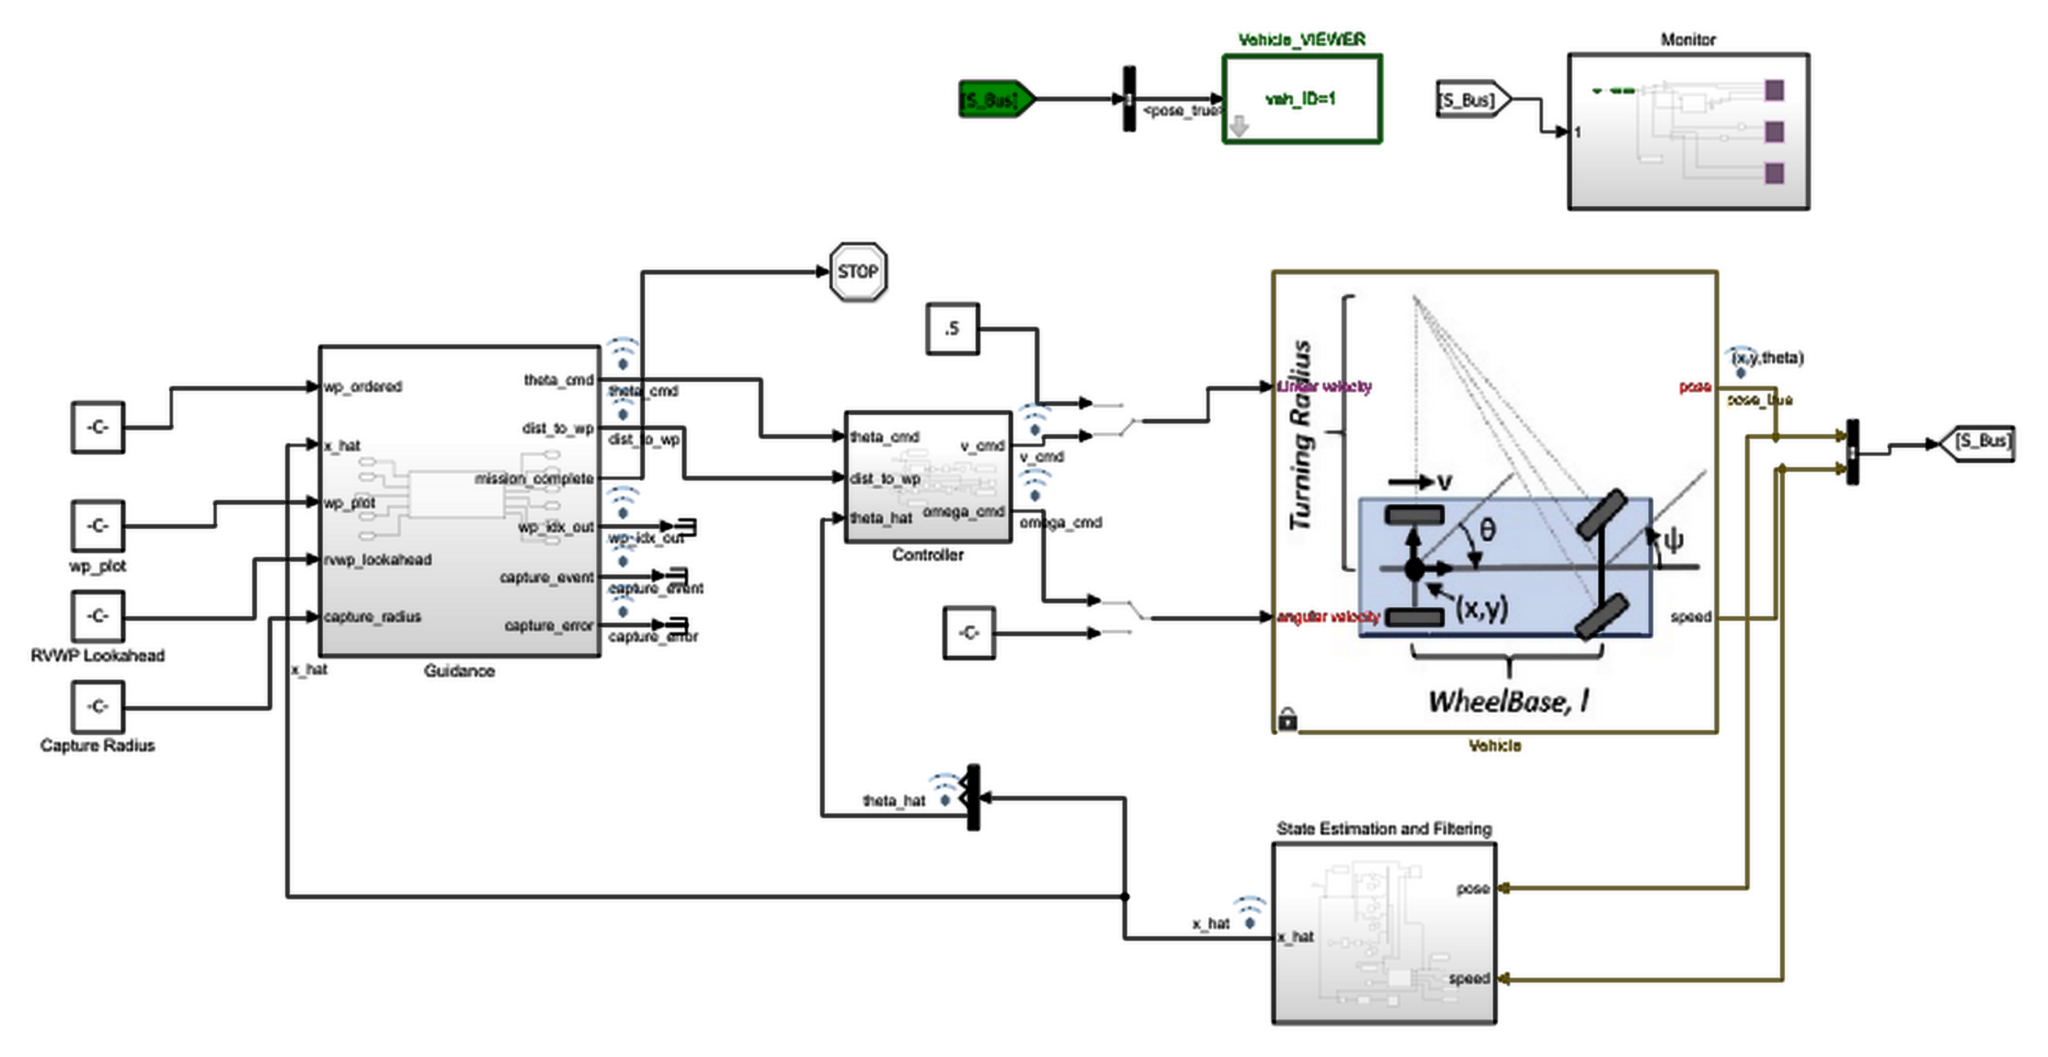

*Figure 1. Integrated ground-vehicle architecture. Estimated pose feeds Guidance, and estimated heading feeds Controller. The upper monitoring branches display and record vehicle behaviour.*

**Guidance** receives the ordered waypoints, plotting route, estimated pose, look-ahead distance and capture radius. Its outputs include the heading command, waypoint distance, waypoint index, capture event, capture error and mission-completion flag.

**Controller** receives the heading command, waypoint distance and estimated heading. It produces linear-speed and turn-rate commands. For autonomous operation, select these controller outputs at the manual switches shown before the Vehicle block.

**Vehicle** models an Ackermann-steered ground robot with internal linear-speed and angular-rate regulation. Its pose and speed outputs feed **State Estimation and Filtering**. The estimator returns the filtered pose to guidance and the heading component to control, closing the feedback loop.

The **Vehicle Viewer** displays the vehicle and its trajectory. The **Monitor** exposes signals for inspection. The mission-completion output connects to the stop block. Reaching the simulation stop time alone does not establish that every waypoint was captured.

## 3. Software requirements and project files

Use the MATLAB/Simulink release agreed for the editable model. The supplied `.slxc` cache contains R2026a metadata; it does not establish the oldest compatible release. The Live Editor formatting in this guide needs R2025a or later.

The underlying toolbox also supports other robot geometries, lidar, object detection and occupancy-map visualisation. Those capabilities can support extensions; this guide documents the supplied waypoint-following architecture.

**Keep the complete folder structure.** The integrated simulation needs `sl_groundvehicleDynamics.slx`, `startupGround.m`, `controller_params.m`, `mdl_robot.m` and its waypoint functions, and `toolboxes/MRTB`. Whole-mission analysis also needs `controller_analysis.m` and `robustness_test.m`. Estimator analysis uses `plot_lkf_results.m` and `param_estimation_constant.m`.

The reviewed attachments contain parameter, startup and analysis scripts, saved data and a simulation cache. They do not contain the editable `.slx` model, `mdl_robot.m`, the active optimiser, `controller_analysis.m` or the toolbox directory. These must come from the complete project checkout. A `.slxc` cache cannot replace the model; `.asv` files are editor backups.

## 4. Select the project folder and execution mode

Set MATLAB's **Current Folder** to the folder containing `startupGround.m` and `toolboxes`. On the first pass, leave `runVehicleSimulation` false to read the guide and run its small numerical examples. Set it true when the complete project is available, then run Sections 4–6 in order. No ten-mission batch is started by Run All.

projectRoot = pwd;
modelName = 'sl_groundvehicleDynamics';
runVehicleSimulation = false;
guideFigureFolder = fullfile(projectRoot, 'Figures');

requiredItems = {
    'startupGround.m'
    'controller_params.m'
    'sl_groundvehicleDynamics.slx'
    'mdl_robot.m'
    fullfile('toolboxes','MRTB')
    'controller_analysis.m'
    'plot_lkf_results.m'
    'param_estimation_constant.m'
    'robustness_test.m'
    };
found = false(size(requiredItems));
for item = 1:numel(requiredItems)
    itemPath = fullfile(projectRoot, requiredItems{item});
    found(item) = isfile(itemPath) || isfolder(itemPath);
end
disp(table(requiredItems, found, ...
    'VariableNames', {'ProjectItem','PresentAtProjectRoot'}))

The table checks the expected root layout. Dependencies inside added project folders may be found later on the MATLAB path. If duplicate copies exist, use `which startupGround -all` and `which controller_params -all` to identify the versions MATLAB will call. Use `ver` to list installed products.

## 5. Start the ground-vehicle environment

The supplied `startupGround` adds toolbox paths, runs the mobile robotics startup function, loads controller parameters, opens the model and clears its `StopFcn` so that analysis is performed manually.

Its first line closes the model with a save flag of zero. Save model edits before restarting. The code below checks for unsaved edits and loads the model first, so the startup script also has a loaded model to close. See [MathWorks: close_system](https://www.mathworks.com/help/simulink/slref/close_system.html).

if runVehicleSimulation
    assert(isfile(fullfile(projectRoot, [modelName '.slx'])), ...
        'The editable sl_groundvehicleDynamics.slx model is required.');
    assert(isfile(fullfile(projectRoot, 'startupGround.m')), ...
        'Set Current Folder to the project root containing startupGround.m.');
    assert(isfolder(fullfile(projectRoot, 'toolboxes', 'MRTB')), ...
        'The bundled toolboxes/MRTB folder is required.');
    assert(strcmp(pwd, projectRoot), ...
        'Return Current Folder to projectRoot before starting.');
    if bdIsLoaded(modelName) && strcmp(get_param(modelName,'Dirty'),'on')
        error('Save your model edits before running startupGround.');
    end
    addpath(genpath(fullfile(projectRoot, 'toolboxes')));
    if ~bdIsLoaded(modelName)
        load_system(fullfile(projectRoot, [modelName '.slx']));
    end
    startupGround;
    fprintf('Current model InitFcn:\n%s\n', ...
        get_param(modelName, 'InitFcn'));
else
    disp('Reading mode: enable runVehicleSimulation in Section 4 to start the model.')
end

For varied-mission testing, the supplied robustness script expects the model's **InitFcn** callback to include the following commands. Inspect the existing callback and retain any additional setup the complete model requires.

Initialise robot and route variables before blocks evaluate them. The guidance and controller parameters are exported to the base workspace by `controller_params`.

## 6. Run and analyse one mission

Select the controller outputs at the manual command switches before running. The viewer should show progress through the route. Check completion using the true captured-waypoint count as well as the guidance completion signal.

if runVehicleSimulation
    simOut = sim(modelName, 'ReturnWorkspaceOutputs', 'on');
    disp('Mission simulation finished. Inspect completion and capture metrics.')
end

Whole-mission analysis and estimator diagnostics use different logging interfaces. The supplied robustness script passes `logsout` to `controller_analysis` through the workspace. The estimator plotting function reads the six separately named outputs listed in Section 10.

Run this example after the mission when the analysis functions are available:

For estimator statistics without plotting, use `estimatorStats = plot_lkf_results(simOut, Plots=false);`. Passing `simOut` explicitly identifies the run being analysed.

## 7. Waypoint generation and optimisation

The mission specification uses ten waypoints, with each horizontal coordinate between −100 m and 100 m. Generation creates the locations; optimisation selects the order in which they are visited.

For an open route beginning at position $p_0$ and visiting ordered waypoints $w_1,\ldots,w_n$, the distance is


$$L=\left\|w_1-p_0\right\|_2+\sum_{i=1}^{n-1}\left\|w_{i+1}-w_i\right\|_2$$


Each term is the straight-line distance between two points. In two dimensions, use Pythagoras: $d=\sqrt{(x_2-x_1)^2+(y_2-y_1)^2}$. Add a return leg only when the mission requires a return to its starting point.

The following example loads the saved route into a structure, preserving the active model's waypoint variables. If the file is absent, it uses a coordinate snapshot from the supplied `fixed_waypoints.mat` so that the calculation can still be explored.

fixedRoutePath = fullfile(projectRoot, 'fixed_waypoints.mat');
if isfile(fixedRoutePath)
    guideRoute = load(fixedRoutePath, 'wp_ordered', 'wp_plot');
    guideRouteSource = 'fixed_waypoints.mat in the project folder';
else
    guideRoute.wp_ordered = [ ...
         4  24
        46  51
        48  45
        89 -35
        27 -89
       -71 -41
       -34 -13
       -38  27
       -38  88
       -87  90];
    guideRoute.wp_plot = [0 0; guideRoute.wp_ordered];
    guideRouteSource = 'snapshot of the supplied fixed-waypoint file';
end
routeXY = double(guideRoute.wp_plot);
segmentLengths = sqrt(sum(diff(routeXY, 1, 1).^2, 2));
openRouteLength = sum(segmentLengths);
fprintf('Route source: %s\n', guideRouteSource);
fprintf('Open-route distance: %.3f m\n', openRouteLength);
disp(table((1:numel(segmentLengths))', segmentLengths, ...
    'VariableNames', {'Leg','Distance_m'}))
figure('Color','w','Name','Saved waypoint route');
plot(routeXY(:,1), routeXY(:,2), '-o', 'LineWidth',1.4);
hold on
plot(routeXY(1,1), routeXY(1,2), 's', ...
    'MarkerSize',9,'MarkerFaceColor',[0.85 0.2 0.15]);
text(guideRoute.wp_ordered(:,1)+2, guideRoute.wp_ordered(:,2), ...
    string((1:size(guideRoute.wp_ordered,1))'));
axis equal
grid on
xlabel('Global x (m)')
ylabel('Global y (m)')
title(sprintf('Saved waypoint order: open route %.1f m', openRouteLength))
legend('Visit order','Starting point','Location','best')
hold off

The supplied plotting route starts at `[0,0]`. For an actual trial, build the plotting route from the robot's actual starting position followed by `wp_ordered`. Otherwise the first-leg distance can be incorrect.

The active optimiser was not included in the reviewed files. Inspect `mdl_robot` and the functions it calls to identify its method, cost, stopping rule and parameters. Compare route lengths using the same waypoint set, start and endpoint convention. A reduced distance does not establish a global optimum, and the shortest geometric route need not have the shortest driving time because sharp turns require slower motion.

## 8. Guidance and control

Guidance computes the geometry between the estimated vehicle position and a target. The target can be the active waypoint or the look-ahead point selected by the guidance implementation. If the target is $(g_x,g_y)$ and the estimated position is $(\hat{x},\hat{y})$, then


$$d=\sqrt{(g_x-\hat{x})^2+(g_y-\hat{y})^2}$$



$$\theta_{cmd}=\operatorname{atan2}(g_y-\hat{y},g_x-\hat{x})$$


The function `atan2` uses both coordinate differences to choose the correct direction. Wrap the difference between commanded and estimated heading to the range −π to π, so that a boundary crossing at ±180° does not create an artificial large error.

**Worked geometry example.** The estimated vehicle pose is `[0,0,10 degrees]` and the target is `[3,4] m`. The distance should be 5 m, the target bearing about 53.13°, and the heading error about 43.13°. Variables beginning with `example` belong only to this calculation.

examplePose = [0, 0, deg2rad(10)];
exampleTarget = [3, 4];
exampleDelta = exampleTarget - examplePose(1:2);
exampleDistance = hypot(exampleDelta(1), exampleDelta(2));
exampleBearing = atan2(exampleDelta(2), exampleDelta(1));
exampleHeadingError = atan2( ...
    sin(exampleBearing - examplePose(3)), ...
    cos(exampleBearing - examplePose(3)));
fprintf('Distance %.2f m, bearing %.2f deg, heading error %.2f deg\n', ...
    exampleDistance, rad2deg(exampleBearing), rad2deg(exampleHeadingError));

The supplied parameter file contains the following active values. Its integral and derivative parameter exports are commented out, so those entries do not establish an active PID implementation.

A proportional heading calculation multiplies heading error by the heading gain and limits the result to the allowed turn-rate interval. The following numerical illustration uses the supplied gain and limit. The actual Controller block must also be checked for its speed scheduling and any additional logic.

exampleHeadingGain = 1;
exampleTurnLimit = 2*pi/5;
exampleTurnCommand = max(-exampleTurnLimit, ...
    min(exampleTurnLimit, exampleHeadingGain*exampleHeadingError));
fprintf('Illustrative proportional turn command: %.4f rad/s\n', ...
    exampleTurnCommand);

The base environment accepts speed commands between −5 and 5 m/s and turn-rate commands between −π/2 and π/2 rad/s, according to the supplied environment guide. The project configuration uses the smaller limits above. Edit persistent tuning in `controller_params.m`: the model callback can overwrite a temporary workspace change at the next initialisation.

The planar motion relationships are $\dot{x}=v\cos\theta$, $\dot{y}=v\sin\theta$, and $\dot{\theta}=\omega$. A dot means rate of change per second. They explain how speed and turning move the vehicle. The Ackermann geometry and internal regulators determine the actual response to the external commands.

Look-ahead and capture radius influence guidance decisions. Test them together with command saturation, cross-track error, true waypoint capture and mission time. An estimated-pose capture event must be checked against ground truth.

## 9. State estimation and filtering

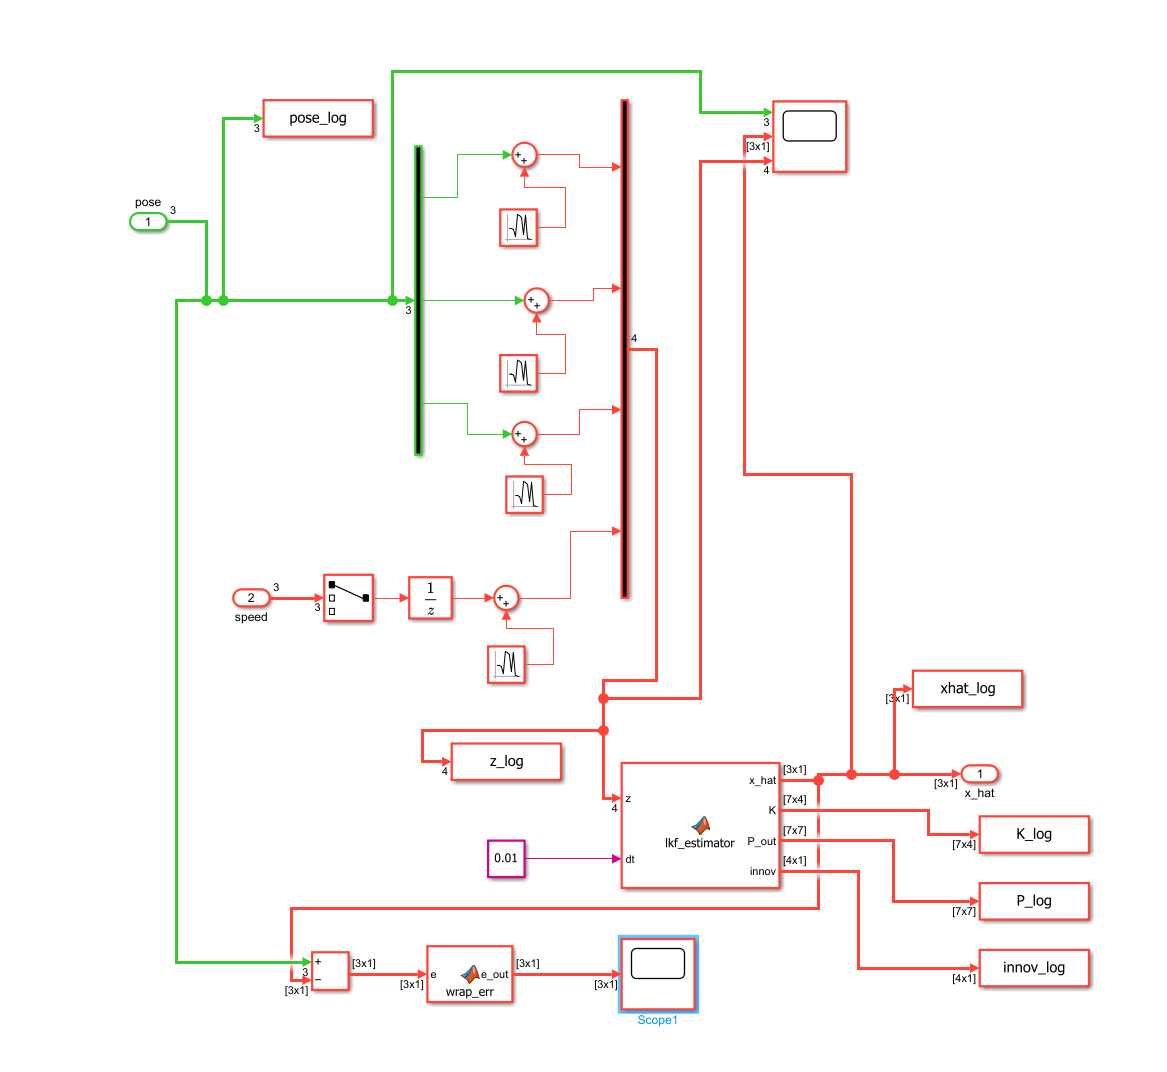

*Figure 2. Internal estimation architecture. Four measurement channels enter the estimator; estimated pose returns to the navigation loop. Separate outputs record pose, gain, covariance and innovations.*

The documented linear Kalman filter has seven internal states in the order `[x, y, theta, v, omega, vx, vy]`. Here `x,y` are global position, `theta` is heading, `v` is forward speed, `omega` is turn rate, and `vx,vy` are global velocity components. Its measurement vector is `[zx, zy, ztheta, zv]`.

At the nominal 0.01 s update interval, the filter first predicts the state using its motion model. It then compares the predicted measurements with the sensor measurements and corrects the estimate. The **innovation** is this measurement-minus-prediction difference; the **Kalman gain** determines how strongly it changes the prediction.

In the update $\hat{\mathbf{x}}^{+}=\hat{\mathbf{x}}^{-}+K(\mathbf{z}-H\hat{\mathbf{x}}^{-})$, the minus superscript means “before using the current measurement”, and the plus superscript means “after the correction”. The matrix $H$ selects or maps the states that the sensors measure. The matrix $K$ converts the measurement differences into state corrections.

Covariance is the filter's predicted uncertainty under its assumptions. A constant-velocity approximation can become inaccurate during turns and acceleration, even when gain and covariance have settled. Confirm the actual state-transition and process-noise settings in the estimator block before tuning.

**Measurement-noise calculation.** Position variance is 0.1 m² on each axis, heading variance is 2 deg², and speed variance is 0.01 (m/s)². Convert a variance by squaring the angle conversion factor; 2 deg² is not the same as a standard deviation of 2 degrees.

exampleSampleTime = 0.01;
exampleHeadingVariance = 2*(pi/180)^2;
exampleR = diag([0.1, 0.1, exampleHeadingVariance, 0.01]);
fprintf('Heading variance: %.8f rad^2\n', exampleHeadingVariance);
fprintf('Heading standard deviation: %.4f degrees\n', sqrt(2));
disp(exampleR)

The speed channel in the supplied architecture passes through a component selector and a one-sample delay. Confirm that the selected component represents the quantity modelled by the speed state. Timestamp alignment in post-processing does not by itself remove physical sensor delay.

## 10. Required estimator outputs

Although the internal estimator has seven states, `xhat_log` is a three-component pose output. The supplied `plot_lkf_results` loader expects the named outputs in `simOut`, a matching structure, or the base workspace. Keeping the signals only inside `logsout` is insufficient for this loader.

After a mission, the following MATLAB example checks the available output names:

Match timestamps and units for truth and estimates. Wrap heading errors using `atan2(sin(error),cos(error))`. The plotting function can align samples using previous-sample hold, but the sensor and estimator timing still needs to match the model.

## 11. Understand the Kalman calculation with one constant

Before examining the seven-state vehicle filter, estimate one fixed value from noisy measurements. The supplied scalar verification uses a true value of 3.7, measurement-noise standard deviation 0.8, initial estimate 0, initial variance 10, and 200 samples.

For a constant with zero process noise, the previous corrected variance is also the next predicted variance. The scalar update is


$$K_k=\frac{P_{k-1}}{P_{k-1}+R},\qquad \hat{c}_k=\hat{c}_{k-1}+K_k(z_k-\hat{c}_{k-1})$$


Here $R=0.8^2=0.64$, $z_k$ is the current noisy measurement, and $P$ is estimation variance. A larger gain makes the estimate move further toward the new measurement. As more independent measurements are collected, uncertainty falls and each additional measurement has less influence.

This self-contained example implements the same scalar recursion. Its Joseph covariance update, `(1-K)^2*P + K^2*R`, is equivalent to `(1-K)*P` in exact arithmetic and helps preserve non-negative variance numerically. The random stream is local to this example.

exampleTruth = 3.7;
exampleNoiseStd = 0.8;
exampleCount = 200;
exampleInitialVariance = 10;
exampleNoiseVariance = exampleNoiseStd^2;
exampleStream = RandStream('mt19937ar','Seed',1);
exampleMeasurements = exampleTruth + ...
    exampleNoiseStd*randn(exampleStream,exampleCount,1);
exampleEstimate = zeros(exampleCount,1);
exampleVariance = zeros(exampleCount,1);
exampleGain = zeros(exampleCount,1);
cEstimate = 0;
pEstimate = exampleInitialVariance;
for k = 1:exampleCount
    gain = pEstimate/(pEstimate + exampleNoiseVariance);
    cEstimate = cEstimate + gain*(exampleMeasurements(k)-cEstimate);
    pEstimate = (1-gain)^2*pEstimate + gain^2*exampleNoiseVariance;
    exampleEstimate(k) = cEstimate;
    exampleVariance(k) = pEstimate;
    exampleGain(k) = gain;
end
closedFormVariance = 1/(1/exampleInitialVariance + ...
    exampleCount/exampleNoiseVariance);
fprintf('Recursive final variance: %.8f\n', exampleVariance(end));
fprintf('Closed-form final variance: %.8f\n', closedFormVariance);
assert(abs(exampleVariance(end)-closedFormVariance) < 1e-12, ...
    'The recursive and closed-form scalar variances should agree.');
figure('Color','w','Name','Scalar Kalman filter example');
subplot(2,1,1)
plot(1:exampleCount,exampleMeasurements,'.','Color',[0.7 0.7 0.7]);
hold on
plot(1:exampleCount,exampleEstimate,'b-','LineWidth',1.4);
yline(exampleTruth,'k--');
grid on
xlabel('Sample k')
ylabel('Constant value')
legend('Measurements','Estimate','True value','Location','best')
title('Scalar estimation from noisy measurements')
hold off
subplot(2,1,2)
plot(1:exampleCount,exampleVariance,'LineWidth',1.4);
grid on
xlabel('Sample k')
ylabel('Estimation variance P')
title('Predicted uncertainty decreases as measurements accumulate')

The independent calculation is $P_{200}=1/(1/10+200/0.64)=0.00319898$. Agreement verifies this covariance recursion; it does not establish vehicle-model accuracy or closed-loop navigation performance.

To run the project's complete scalar analysis and save its five PNG figures, use the supplied function:

That function sets the global random seed. Run it separately from a controlled vehicle trial, or restore the intended randomisation before the vehicle run.

## 12. Controlled trials and robustness testing

**Compare designs on a repeatable mission.** Keep the waypoint set, initial pose, noise conditions, simulation settings and evaluation window the same when comparing guidance, controller or estimator settings. Change one design choice at a time.

A controlled-trial **InitFcn** can follow this pattern. These are callback instructions to apply in the model, so the example is shown as formatted code rather than executed during the tutorial:

Load the fixed waypoints after generation so that initialisation does not immediately overwrite them. The plotting route starts at the actual initial pose. Verify that `mdl_robot` and sensor blocks do not use independent seeds or streams; fixed waypoints alone do not fix the initial pose or sensor noise.

**Evaluate varied missions.** Restore the random-mission callback containing `mdl_robot; controller_params;`, retaining necessary model setup and removing fixed-waypoint loading and per-run fixed reseeding. Save previous results that must be retained, then run this command in the MATLAB Command Window:

The supplied script runs ten missions and expects initialisation to regenerate the robot start, waypoints and optimised order. It begins with `clear` and writes fixed output filenames. It is kept outside automatic tutorial execution so that its workspace clearing and long batch do not interrupt the guide.

The archive does not retain every random-generator state or estimator setting. Record these separately when exact replay is required.

## 13. Evaluate the whole system

For position errors $e_{x,k}$ and $e_{y,k}$ over $N$ matched samples, planar RMSE is


$$\mathrm{RMSE}_{xy}=\sqrt{\frac{1}{N}\sum_{k=1}^{N}(e_{x,k}^{2}+e_{y,k}^{2})}$$


This measures localisation error: the distance between estimated and true position. Cross-track error instead measures how far the true vehicle position lies from the reference path. A good estimator can accurately report that the vehicle is following the path poorly.

For uncertainty checks, compare innovation variation with $S=HP^{-}H^{T}+R$, using the covariance before the current measurement correction. Settled covariance alone is insufficient evidence of calibration. Report the evaluation window, initial transient treatment and heading units for every RMSE comparison.

The supplied estimator analysis uses a nominal 0.01 s interval and a default steady-evaluation start at sample 500, capped for short records. Use the same interval and window when comparing designs. Compare mission time alongside route length, since different missions can require different amounts of travel.

## 14. Figures and troubleshooting

Both supplied plotting functions default to a lowercase `figures` folder beside their function files. The examples here explicitly use `Figures` to match the report directory. The scalar function creates five diagnostic PNGs, and the vehicle-estimator function creates nine. Use the same folder capitalisation on case-sensitive systems.

## 15. Documentation and scope

Project commands, parameter values, logged-output names and saved-data structure were checked against the supplied MATLAB files. The numerical examples are explicitly identified as examples. The complete Simulink model and MATLAB Live Editor were not available for execution during preparation.

[Mobile Robotics Simulation Toolbox](https://github.com/mathworks-robotics/mobile-robotics-simulation-toolbox) provides the environment documentation, kinematic examples and visualisation utilities. Original toolbox copyright: The MathWorks, Inc., 2018–2019.

MATLAB references: [Live Code file format](https://www.mathworks.com/help/matlab/matlab_prog/plain-text-file-format-for-live-scripts.html), [function argument validation](https://www.mathworks.com/help/matlab/ref/arguments.html), and [name-value calls](https://www.mathworks.com/help/matlab/matlab_prog/namevalue-in-function-calls.html).